# Test Limit Commands Function

Objective: This script tests the *limitCommands* function. It uses the kinematic equations defined in the *plot_nonholonomic_kinematics* script and plots limited commands based on the allowable maximum wheel speed. 

Helper Functions used in this exercise:

    plot_robot: plots the

-  robot

-   visual representation (blue arrow) of the (1) velocty of the right wheel, (2) velocity of the left wheel, (3) overall velocity

-   trajectory of the robot (red line) based on the solved control inputs

**EXERCISE:**

We will use the *plot_nonholonomic_kinematics *script to set up the kinematic equations. Go back to that file and try different values for  uR and uL. Pick high values for uR and uL to make sure you see the effects of the *limitCommands* function. 

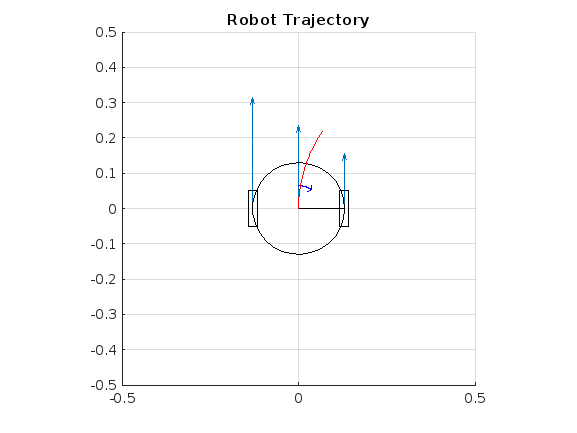

plot_nonholonomic_kinematics 

The code below tests the *limitCommands* function and plots the trajectory using the new control inputs. 

[V, w, scaleFactor] = limitCommands(V, warning, maxWheelSpeed);

Operator '*' is not supported for operands of type 'struct'.

Error in limitCommands (line 9)
uR = (2*fwdVel + L*angVel)/(2*r); % YOUR CODE HERE


figure; 
plot_title = "Robot Trajectory - Scaled commands"; 
plot_robot(uR, uL, V, w, L, r, plot_title);
set(gcf,'Visible','on')

Expected Results: 

This script produces two plots to compare the unscaled and scaled commands for the robot velocities. The plots should have the same curvature, however since scaled commands slow down the vehicle - the trajectory will be shorter. 

Check your Comprehension: 

After testing different values for  uR and uL, how do they relate? If you wanted to sharply turn in one direction how would you set  uR and uL? If you wanted to move forward, how would you set  uR and uL? Why does it make more sense to command the Create robot using V and ω rather than uR and uL?